# **Data Simulation from KIDI Code**

**This code simulates data using KIDI, a novel theoretical framewok that represents interspecies interactions as a function of environmental variables with growth kinetics and a generalized Lotka-Volterra model. This framework was tested on a synthetic consortium of two auxotrophic *****Escherichia coli *****mutants. The two *****E. coli *****species are unable to grow without the other due to an inability to synthesize an essential amino acid (tryptophan and tyrosine). The simulated data was compared against experimental data from experiments that were done with this synthetic consortium with different starting concentrations of tyrosine, tryptophan and glucose in batch and fed-batch experiments.**

**Background information from original experiment: **

- **Exps 1 - 3:** x1 (delTrp *E. coli*) only (Exp1 = trp 10 mg/l, Exp2 = trp 20 mg/l, Exp3 = trp 40 mg/l)

- **Exps 4 - 6:** x2 (delTyr *E. coli*) only (Exp4 = tyr 10 mg/l, Exp5 = tyr 20 mg/l, Exp6 = tyr 40 mg/l)

- **Exps 7 - 9:** measure x1 (delTrp *E. coli*) and x2 (delTyr *E. coli*) separately (Exp10 = batch + no trp + no tyr, Exp11 = 3fb + 0.4 mg/l trp & tyr at time 7.5 hr, Exp12 = 5fb + 0.4 mg/l trp & tyr at time 7.5 hr)

- **Exps 10 - 12:** measure sum of x1 (delTrp *E. coli*) and x2 (delTyr *E. coli*) (Exp7 = batch + no trp + no tyr, Exp8 = 3fb + 0.4 mg/l trp & tyr at time 7.5 hr, Exp9 = 3fb + 200 mg/l trp & tyr at time 10 hr)

#### **In this section, we simulated the 12 original experiments and plotted it as a figure against the experimental data.**

**Fig 2a. Shows simulated data and experimental data from Experiments 1 - 3.**

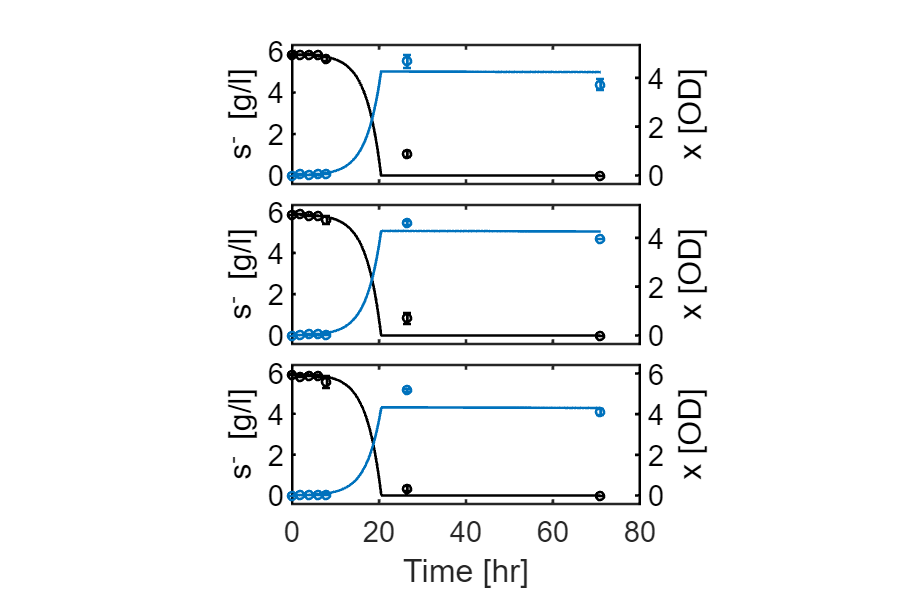

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

%Exp 1
y0 =  [0.01 0 5.838 10 0];  %x1, x2, glc, trp, tyr
tEnd = 71; %Time when experiment is done
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;
Texp = para.Texp_1;
Yexp = para.Yexp_1;
Ystd=para.Ystd_1;

odeOptions=odeset('NonNegative',1:5);
[T,Y] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

nexttile
yyaxis left
plot(T,Y(:,3),'linewidth',2,'Color','k')
hold on
errorbar(Texp,Yexp(:,3),Ystd(:,3),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xlim([0 80])
xticks([0 20 40 60 80])
set(gca, 'XTickLabel', [])
yyaxis right
plot(T,Y(:,1),'Color','#0072BD','linewidth',2)
hold on
errorbar(Texp,Yexp(:,1),Ystd(:,1),'ko','linewidth',2,'Color','#0072BD')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off


%Exp 2
y0 =  [0.01 0 5.870 20 0];
tEnd = 71;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;
Texp = para.Texp_2;
Yexp = para.Yexp_2;
Ystd=para.Ystd_2;

odeOptions=odeset('NonNegative',1:5);
[T,Y] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

nexttile
yyaxis left
plot(T,Y(:,3),'linewidth',2,'Color','k')
hold on
errorbar(Texp,Yexp(:,3),Ystd(:,3),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xlim([0 80])
xticks([0 20 40 60 80])
set(gca, 'XTickLabel', [])
yyaxis right
plot(T,Y(:,1),'Color','#0072BD','linewidth',2)
hold on
errorbar(Texp,Yexp(:,1),Ystd(:,1),'ko','linewidth',2,'Color','#0072BD')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off


%Exp 3
y0 =  [0.01 0 5.936 40 0];
tEnd = 71;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;
Texp = para.Texp_3;
Yexp = para.Yexp_3;
Ystd=para.Ystd_3;

odeOptions=odeset('NonNegative',1:5);
[T,Y] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

nexttile
yyaxis left
plot(T,Y(:,3),'linewidth',2,'Color','k')
hold on
errorbar(Texp,Yexp(:,3),Ystd(:,3),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xlim([0 80])
xticks([0 20 40 60 80])
xticklabels({'0','20','40','60','80'})
xlabel('Time [hr]')
yyaxis right
plot(T,Y(:,1),'Color','#0072BD','linewidth',2)
hold on
errorbar(Texp,Yexp(:,1),Ystd(:,1),'ko','linewidth',2,'Color','#0072BD')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig 2b. Shows simulated data and experimental data from Experiments 4 - 6.**

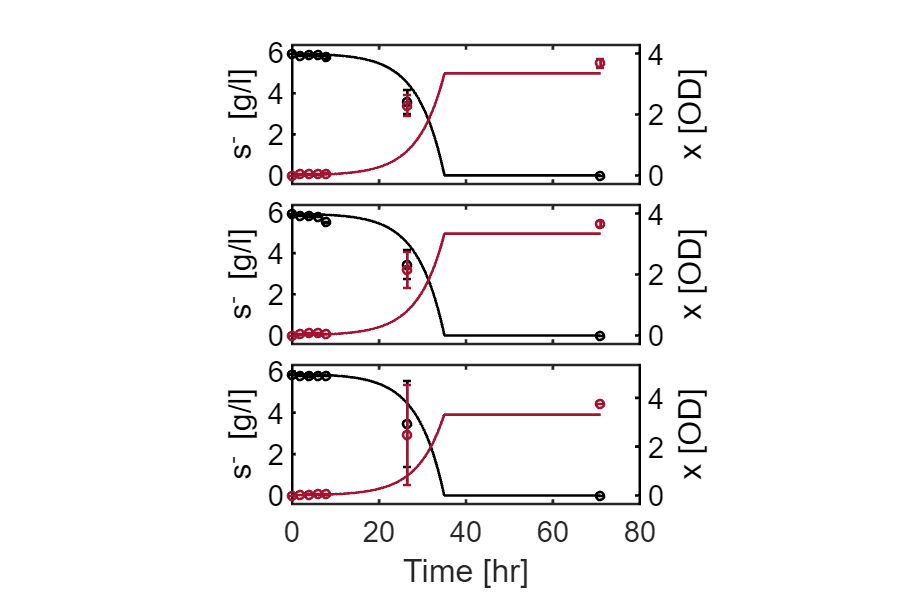

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

%Exp 4
y0 =  [0 0.01 5.920 0 10];  %x1, x2, glc, trp, tyr
tEnd = 71; %Time when experiment is done
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;
Texp = para.Texp_4;
Yexp = para.Yexp_4;
Ystd=para.Ystd_4;

odeOptions=odeset('NonNegative',1:5);
[T,Y] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2)
hold on
errorbar(Texp,Yexp(:,3),Ystd(:,3),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xlim([0 80])
xticks([0 20 40 60 80])
set(gca, 'XTickLabel', [])
yyaxis right
plot(T,Y(:,2),'Color','#A2142F','linewidth',2)
hold on
errorbar(Texp,Yexp(:,2),Ystd(:,2),'ko','linewidth',2,'Color','#A2142F')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off


%Exp 5
y0 =  [0 0.01 5.909 0 20];
tEnd = 71;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;
Texp = para.Texp_5;
Yexp = para.Yexp_5;
Ystd=para.Ystd_5;

odeOptions=odeset('NonNegative',1:5);
[T,Y] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2)
hold on
errorbar(Texp,Yexp(:,3),Ystd(:,3),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xlim([0 80])
xticks([0 20 40 60 80])
set(gca, 'XTickLabel', [])
yyaxis right
plot(T,Y(:,2),'Color','#A2142F','linewidth',2)
hold on
errorbar(Texp,Yexp(:,2),Ystd(:,2),'ko','linewidth',2,'Color','#A2142F')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off


%Exp 6
y0 =  [0 0.01 5.863 0 40];
tEnd = 71;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;
Texp = para.Texp_6;
Yexp = para.Yexp_6;
Ystd=para.Ystd_6;

odeOptions=odeset('NonNegative',1:5);
[T,Y] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2)
hold on
errorbar(Texp,Yexp(:,3),Ystd(:,3),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xlim([0 80])
xticks([0 20 40 60 80])
xticklabels({'0','20','40','60','80'})
xlabel('Time [hr]')
yyaxis right
plot(T,Y(:,2),'Color','#A2142F','linewidth',2)
hold on
errorbar(Texp,Yexp(:,2),Ystd(:,2),'ko','linewidth',2,'Color','#A2142F')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig 2c. Shows simulated data and experimental data from Experiments 7 - 9.**

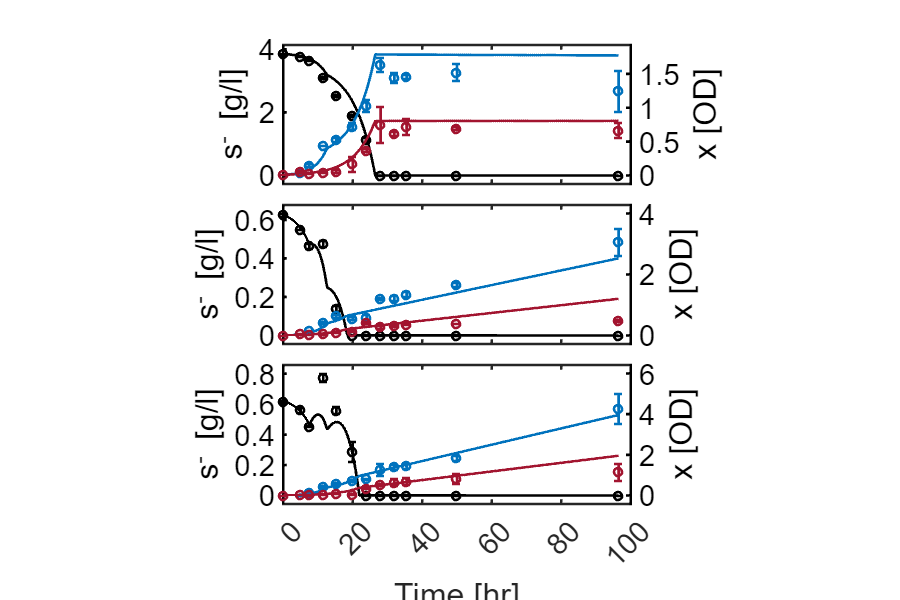

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

%Exp 7
y0 =  [0.01 0.01 3.850866875 0.4 0.4];  %x1, x2, glc, trp, tyr
tEnd = 96.5; %Time when experiment is done
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;
Texp = para.Texp_7;
Yexp = para.Yexp_7;
Ystd=para.Ystd_7;

odeOptions=odeset('NonNegative',1:5);
[T,Y] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
hold on
errorbar(Texp,Yexp(:,3),Ystd(:,3),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xlim([0 100])
xticks([0 20 40 60 80 100])
set(gca, 'XTickLabel', [])
yyaxis right
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
errorbar(Texp,Yexp(:,1),Ystd(:,1),'ko','linewidth',2,'Color','#0072BD')
errorbar(Texp,Yexp(:,2),Ystd(:,2),'ko','linewidth',2,'Color','#A2142F')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off


%Exp 8
y0 =  [0.01 0.01 0.62597 0.4 0.4];
tAdd = 7.5;
tEnd = 96.5;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;
Texp = para.Texp_8;
Yexp = para.Yexp_8;
Ystd=para.Ystd_8;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
hold on
errorbar(Texp,Yexp(:,3),Ystd(:,3),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xticks([0 20 40 60 80 100])
xlim([0 100])
set(gca, 'XTickLabel', [])
yyaxis right
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
errorbar(Texp,Yexp(:,1),Ystd(:,1),'ko','linewidth',2,'Color','#0072BD')
errorbar(Texp,Yexp(:,2),Ystd(:,2),'ko','linewidth',2,'Color','#A2142F')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off

%Exp 9
y0 =  [0.01 0.01 0.620 0.4 0.4];
tAdd = 7.5;
tEnd = 96.5;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;
Texp = para.Texp_9;
Yexp = para.Yexp_9;
Ystd=para.Ystd_9;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797*5/3;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
hold on
errorbar(Texp,Yexp(:,3),Ystd(:,3),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xticks([0 20 40 60 80 100])
xticklabels({'0','20','40','60','80','100'})
xlim([0 100])
xlabel('Time [hr]')
yyaxis right
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
errorbar(Texp,Yexp(:,1),Ystd(:,1),'ko','linewidth',2,'Color','#0072BD')
errorbar(Texp,Yexp(:,2),Ystd(:,2),'ko','linewidth',2,'Color','#A2142F')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig 2d. Shows simulated data and experimental data from Experiments 10 - 12.**

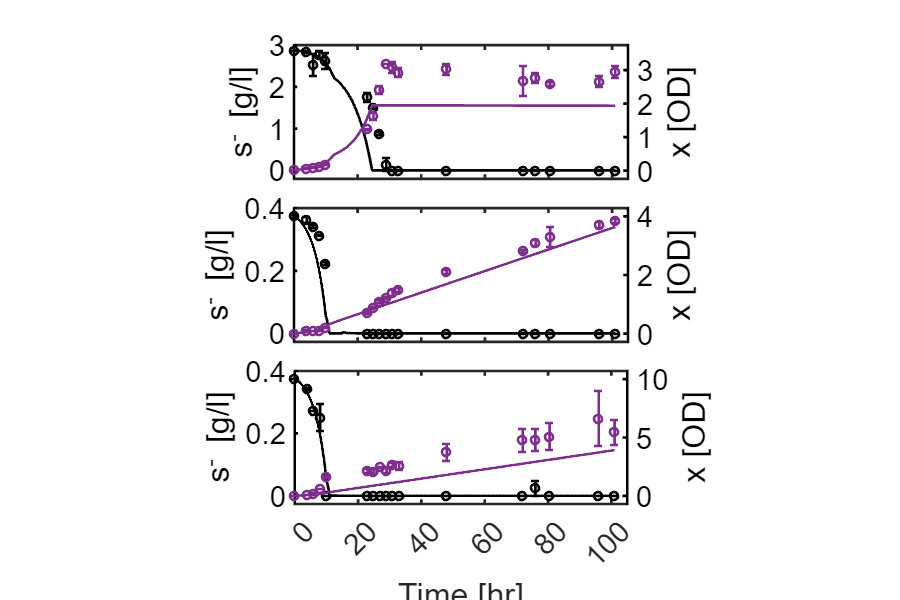

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

%Exp 10
y0 =  [0.01 0.01 2.879738438 0.4 0.4];  %x1, x2, glc, trp, tyr
tEnd = 101; %Time when experiment is done
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;
Texp = para.Texp_10;
Yexp = para.Yexp_10;
Ystd=para.Ystd_10;

odeOptions=odeset('NonNegative',1:5);
[T,Y] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2)
hold on
errorbar(Texp,Yexp(:,2),Ystd(:,2),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xlim([0 105])
xticks([0 20 40 60 80 100])
xticklabels({'0','20','40','60','80','100'})
set(gca, 'XTickLabel', [])
yyaxis right
plot(T,Y(:,1)+Y(:,2),'Color','#7E2F8E','linewidth',2)
hold on
errorbar(Texp,Yexp(:,1),Ystd(:,1),'ko','linewidth',2,'Color','#7E2F8E')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off


%Exp 11
y0 =  [0.01 0.01 0.375339893 0.4 0.4];
tAdd = 10;
tEnd = 101;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;
Texp = para.Texp_11;
Yexp = para.Yexp_11;
Ystd=para.Ystd_11;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2)
hold on
errorbar(Texp,Yexp(:,2),Ystd(:,2),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xticks([0 20 40 60 80 100])
xlim([0 105])
set(gca, 'XTickLabel', [])
yyaxis right
plot(T,Y(:,1)+Y(:,2),'Color','#7E2F8E','linewidth',2)
hold on
errorbar(Texp,Yexp(:,1),Ystd(:,1),'ko','linewidth',2,'Color','#7E2F8E')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off


%Exp 12
y0 =  [0.01 0.01 0.377 200 200];
tAdd = 10;
tEnd = 101;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;
Texp = para.Texp_12;
Yexp = para.Yexp_12;
Ystd=para.Ystd_12;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2)
hold on
errorbar(Texp,Yexp(:,2),Ystd(:,2),'ko','linewidth',2)
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
ylabel('s^- [g/l]')
ylim padded
xticks([0 20 40 60 80 100])
xticklabels({'0','20','40','60','80','100'})
xlim([0 105])
xlabel('Time [hr]')
yyaxis right
plot(T,Y(:,1)+Y(:,2),'Color','#7E2F8E','linewidth',2)
hold on
errorbar(Texp,Yexp(:,1),Ystd(:,1),'ko','linewidth',2,'Color','#7E2F8E')
ylabel('x [OD]')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
pbaspect([2.5 1 1])
hold off

#### **____________________________________________________________________________**

#### **In this section, we start with new intial substrate concentrations. Included in Figure 3&4 are concentrations of substrates (top), and biomass (2nd from top), gamma--the universal interaction parameter (3rd from top), total impact of one species on the other (3rd from bottom), positive impact (2nd from bottom), and negative impact (bottom).**

#### **To better understand the impact of one species on the other, we have enlargened these bottom 3 figures from Figures 3&4, and can be seen in Figures S1&S2 respectively. **

**Fig 3a. Start with a concentration of 2 g/l glucose and 1 mg/l Trp & Tyr each**

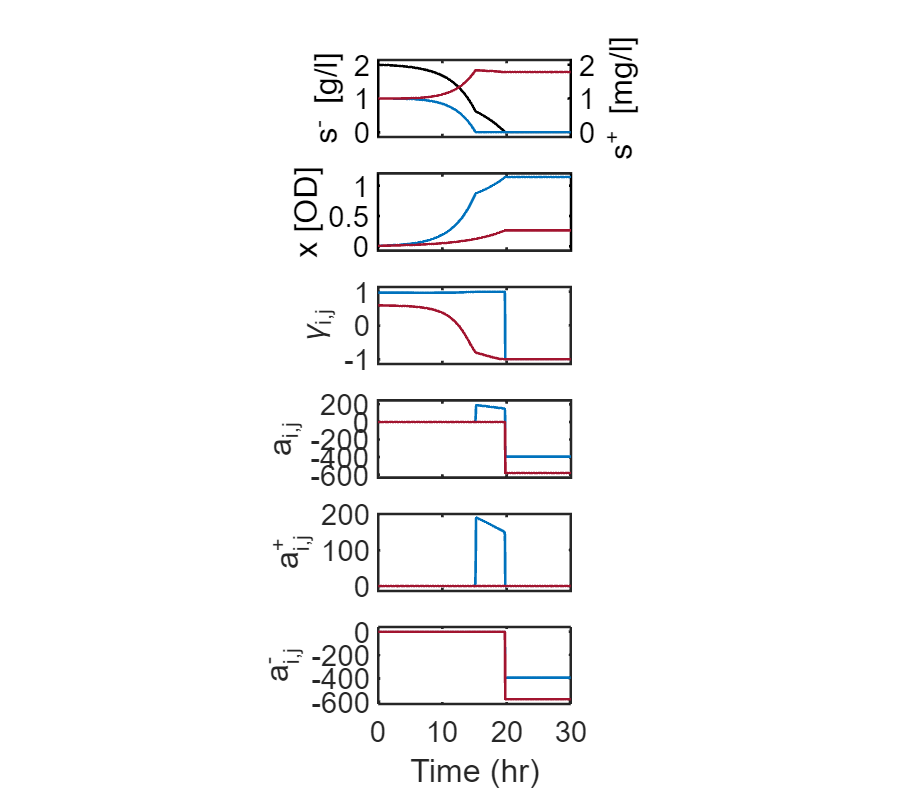

y0 =  [0.01 0.01 2 1 1];  %x1, x2, glc, trp, tyr
tEnd = 30; %Time when experiment is done
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;

odeOptions=odeset('NonNegative',1:5);
[T,Y] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

[a12,a21,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);
a11 = a12(:,1)+a12(:,2);
a22 = a21(:,1)+a21(:,2);

figure('Renderer', 'painters', 'Position', [10 10 900 800])
tiledlayout(6,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded 
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD')
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'XTickLabel',[])
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
ylim padded
xlim([0 30])
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
ylim padded
xlim([0 30])
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
xlabel('Time (hr)')
hold off

**__________________________________________________________________________________**

**Fig S1a. Enlargment of bottom 3 plots from Fig 3a**

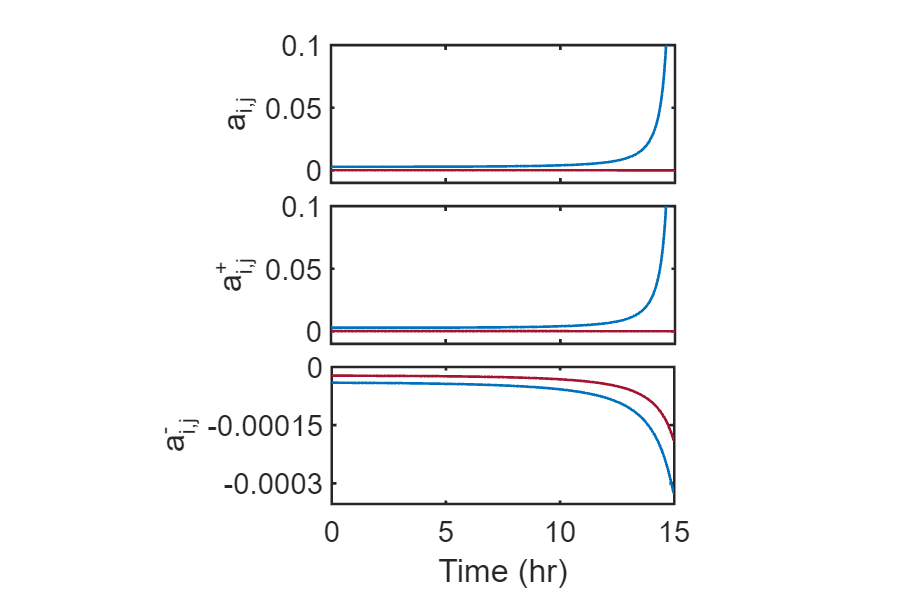

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
xlim([0 15])
ylim padded
ylim([-0.01 0.1])
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
xlim([0 15])
ylim padded
ylim([-0.01 0.1])
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
xlim([0 15])
ylim padded
yticks([-0.0003 -0.00015 0])
yticklabels({'-0.0003', '-0.00015', '0'})
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig 3b. Start with a concentration of 0.5 g/l glucose and 1 mg/l Trp & Tyr each**

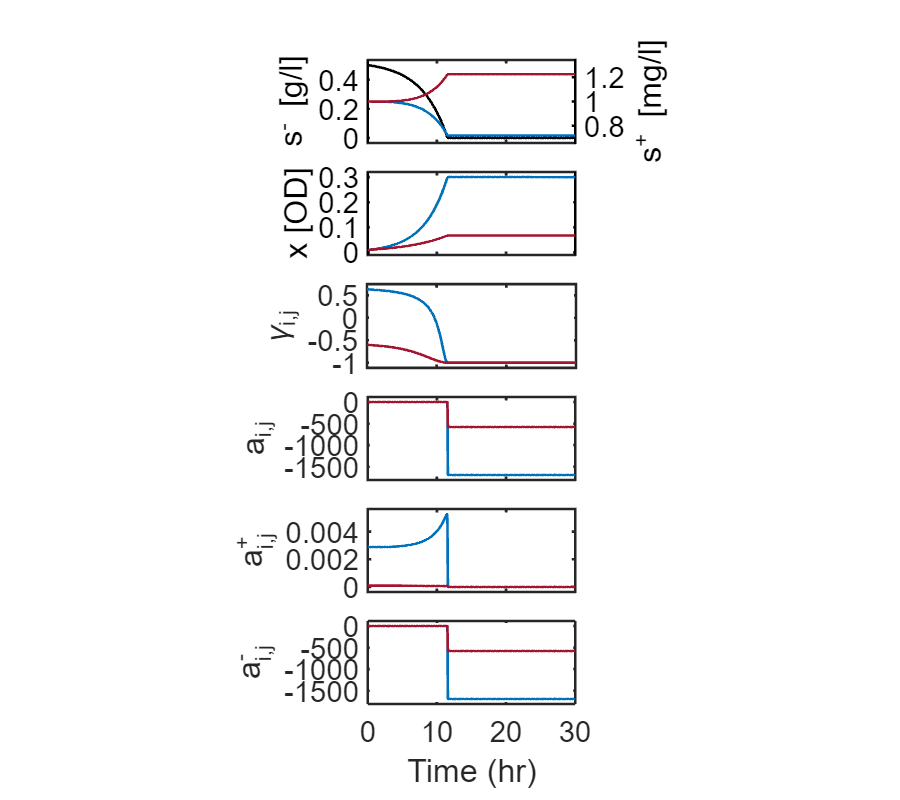

y0 =  [0.01 0.01 0.5 1 1];  %x1, x2, glc, trp, tyr
tEnd = 30; %Time when experiment is done
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;

odeOptions=odeset('NonNegative',1:5);
[T,Y] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

[a12,a21,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);
a11 = a12(:,1)+a12(:,2);
a22 = a21(:,1)+a21(:,2);

figure('Renderer', 'painters', 'Position', [10 10 900 800])
tiledlayout(6,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded 
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD')
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'XTickLabel',[])
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
ylim padded
yticks([0 0.002 0.004])
yticklabels({'0', '0.002', '0.004'})
xlim([0 30])
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
ylim padded
xlim([0 30])
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
xlabel('Time (hr)')
hold off

**__________________________________________________________________________________**

**Fig S1b. Enlargment of bottom 3 plots from Fig 3b**

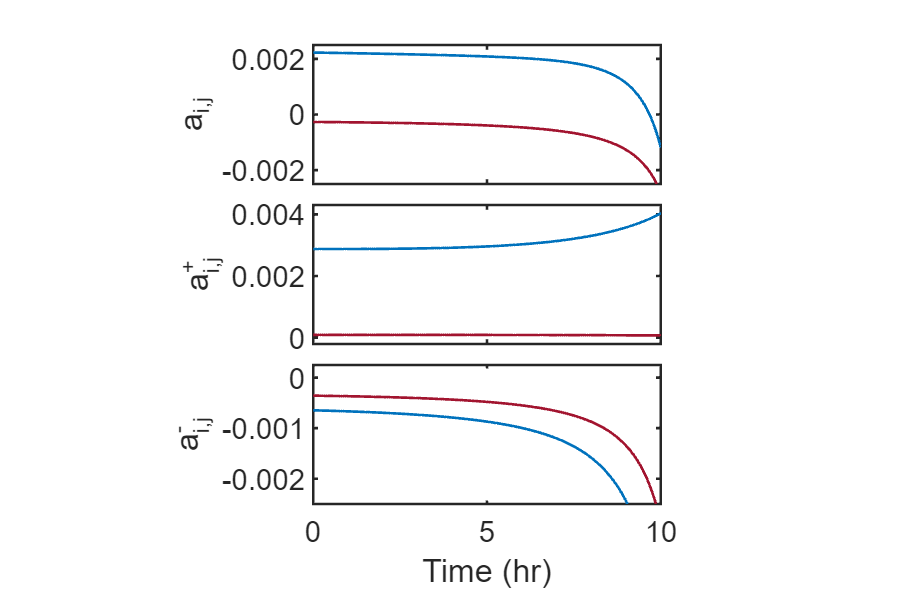

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
xlim([0 10])
ylim([-0.0025 0.0025])
yticks([-0.002 0 0.002])
yticklabels({'-0.002','0','0.002'})
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
xlim([0 10])
ylim padded
yticks([0 0.002 0.004])
yticklabels({'0', '0.002', '0.004'})
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
xlim([0 10])
ylim([-0.0025 0.00025])
yticks([-0.002 -0.001 0])
yticklabels({'-0.002','-0.001','0'})
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig 3c. Start with a concentration of 0.5 g/l glucose and 4 mg/l Trp & Tyr each**

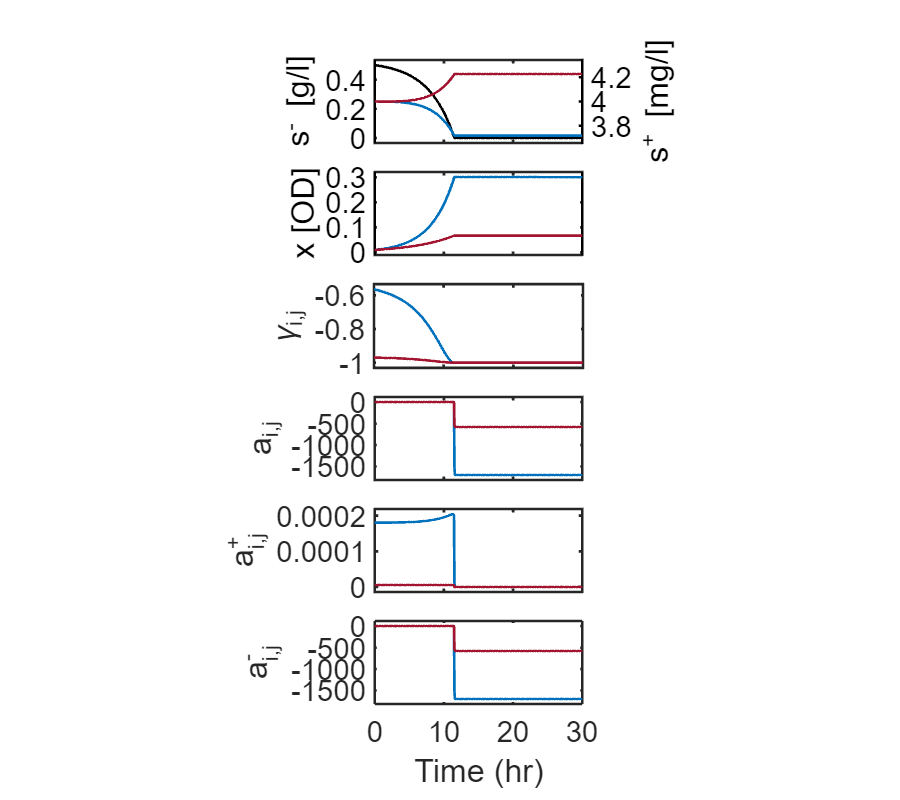

y0 =  [0.01 0.01 0.5 4 4];  %x1, x2, glc, trp, tyr
tEnd = 30; %Time when experiment is done
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;

odeOptions=odeset('NonNegative',1:5);
[T,Y] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

[a12,a21,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);
a11 = a12(:,1)+a12(:,2);
a22 = a21(:,1)+a21(:,2);

figure('Renderer', 'painters', 'Position', [10 10 900 800])
tiledlayout(6,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded 
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD')
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'XTickLabel',[])
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
ylim padded
yticks([0 0.0001 0.0002])
yticklabels({'0','0.0001','0.0002'})
xlim([0 30])
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
ylim padded
xlim([0 30])
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
xlabel('Time (hr)')
hold off

**__________________________________________________________________________________**

**Fig S1c. Enlargment of bottom 3 plots from Fig 3c**

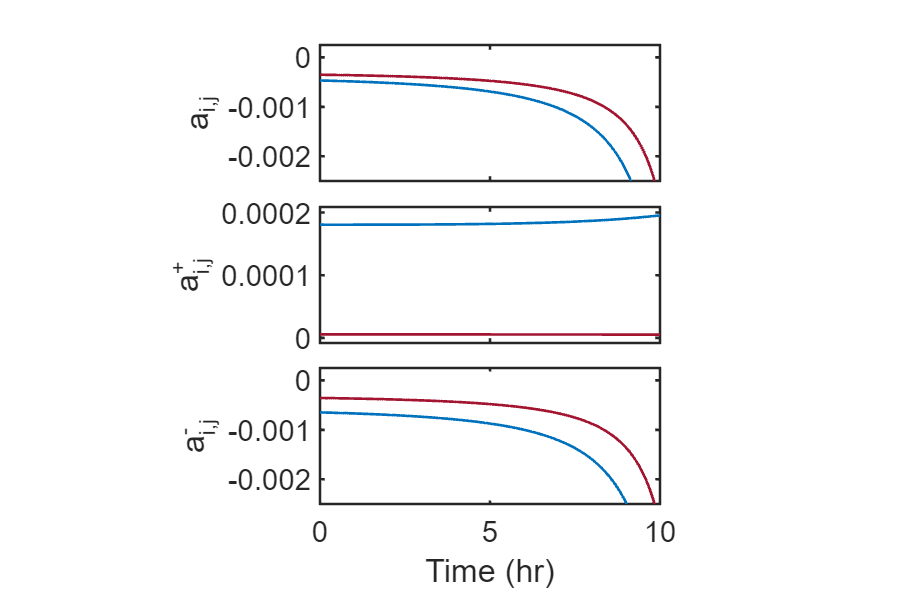

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
xlim([0 10])
ylim([-0.0025 0.00025])
yticks([-0.002 -0.001 0])
yticklabels({'-0.002','-0.001','0'})
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
xlim([0 10])
ylim padded
yticks([0 0.0001 0.0002])
yticklabels({'0','0.0001','0.0002'})
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
xlim([0 10])
ylim([-0.0025 0.00025])
yticks([-0.002 -0.001 0])
yticklabels({'-0.002','-0.001','0'})
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig 4a. Start with a concentration of 2 g/l glucose and 1 mg/l Trp & Tyr each, and add 3FBs at 7.5 hrs**

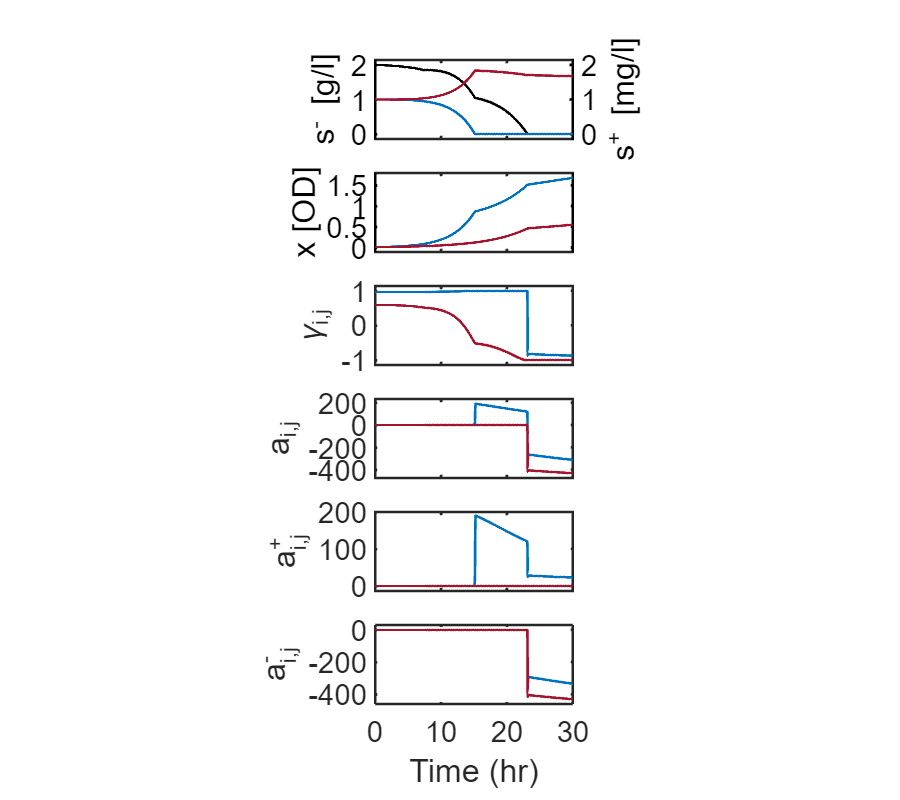

y0 =  [0.01 0.01 2 1 1];  %x1, x2, glc, trp, tyr
tAdd = 7.5;
tEnd = 30;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[a12,a21,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);
a11 = a12(:,1)+a12(:,2);
a22 = a21(:,1)+a21(:,2);

figure('Renderer', 'painters', 'Position', [10 10 900 800])
tiledlayout(6,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded 
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD')
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'XTickLabel',[])
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
ylim padded
xlim([0 30])
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
ylim padded
xlim([0 30])
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
xlabel('Time (hr)')
hold off

**__________________________________________________________________________________**

**Fig S2a. Enlargment of bottom 3 plots from Fig 4a**

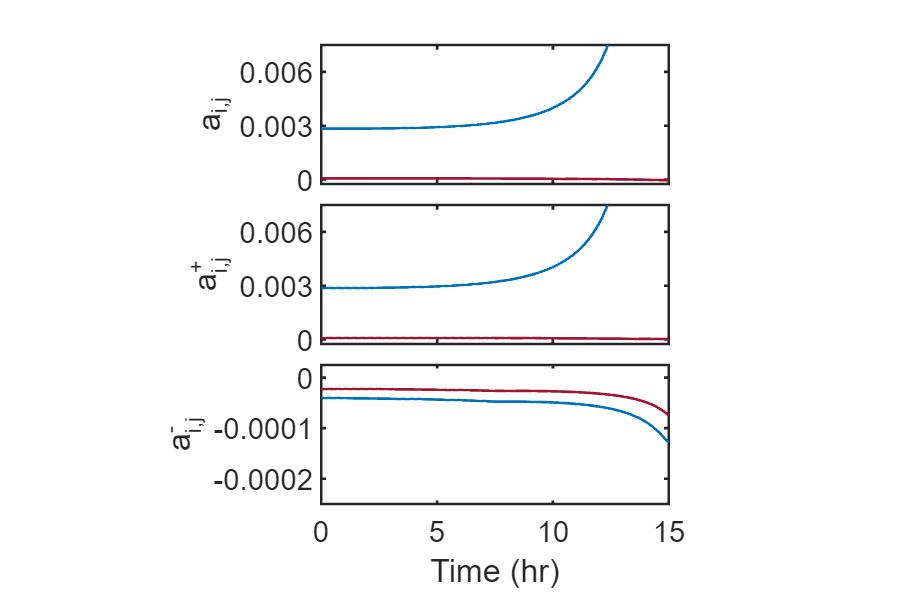

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
xlim([0 15])
ylim([-0.00025 0.0075])
yticks([0 0.003 0.006])
yticklabels({'0','0.003', '0.006'})
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
xlim([0 15])
ylim padded
ylim([-0.00025 0.0075])
yticks([0 0.003 0.006])
yticklabels({'0','0.003', '0.006'})
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
xlim([0 15])
ylim([-0.00025 0.000025])
yticks([-0.0002 -0.0001 0])
yticklabels({'-0.0002','-0.0001','0'})
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig 4b. Start with a concentration of 0.5 g/l glucose and 1 mg/l Trp & Tyr each, and add 3FBs at 7.5 hrs**

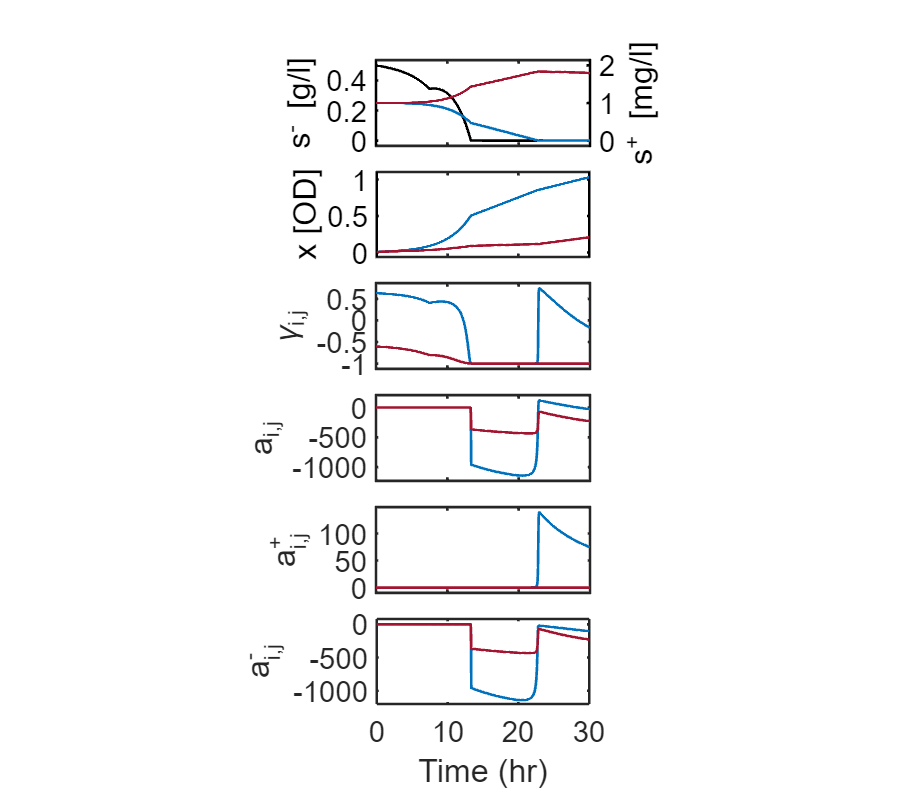

y0 =  [0.01 0.01 0.5 1 1];  %x1, x2, glc, trp, tyr
tAdd = 7.5;
tEnd = 30;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[a12,a21,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);
a11 = a12(:,1)+a12(:,2);
a22 = a21(:,1)+a21(:,2);

figure('Renderer', 'painters', 'Position', [10 10 900 800])
tiledlayout(6,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded 
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD')
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'XTickLabel',[])
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
ylim padded
xlim([0 30])
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
ylim padded
xlim([0 30])
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
xlabel('Time (hr)')
hold off

**__________________________________________________________________________________**

**Fig S2b.  Enlargment of bottom 3 plots from Fig 4b**

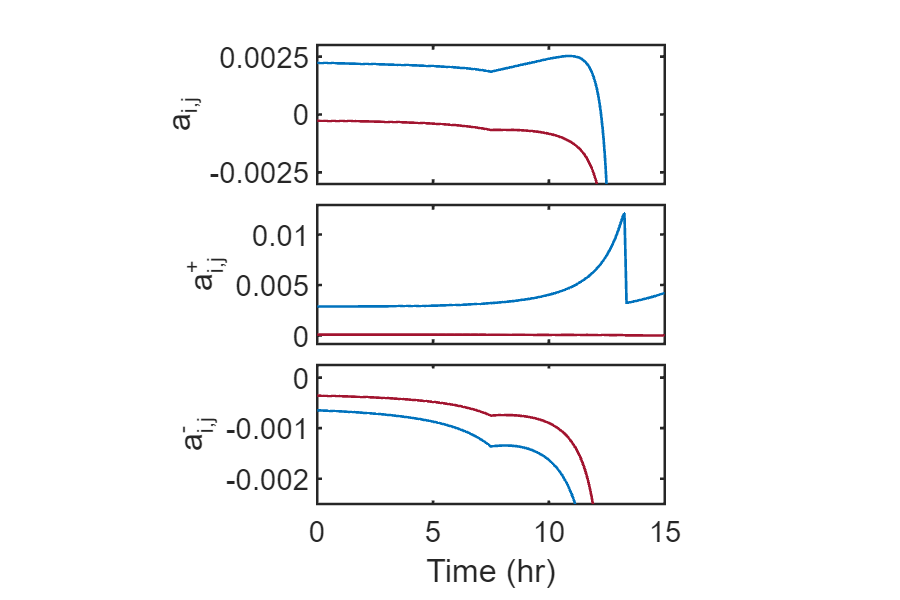

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
xlim([0 15])
ylim([-0.003 0.003])
yticks([-0.0025 0 0.0025])
yticklabels({'-0.0025','0','0.0025'})
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
xlim([0 15])
ylim padded
yticks([0 0.005 0.01])
yticklabels({'0', '0.005', '0.01'})
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
xlim([0 15])
ylim([-0.0025 0.00025])
yticks([-0.002 -0.001 0])
yticklabels({'-0.002','-0.001','0'})
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig 4c. Start with a concentration of 0.5 g/l glucose and 4 mg/l Trp & Tyr each, and add 3FBs at 7.5 hrs**

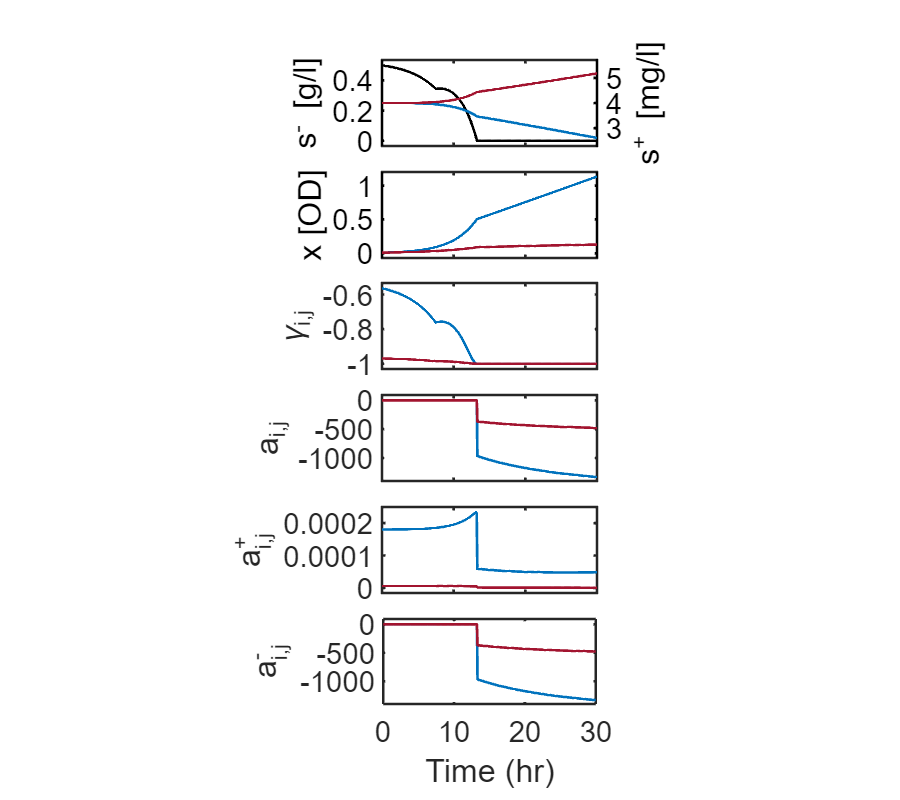

y0 =  [0.01 0.01 0.5 4 4];  %x1, x2, glc, trp, tyr
tAdd = 7.5;
tEnd = 30;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[a12,a21,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);
a11 = a12(:,1)+a12(:,2);
a22 = a21(:,1)+a21(:,2);

figure('Renderer', 'painters', 'Position', [10 10 900 800])
tiledlayout(6,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded 
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD')
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'XTickLabel',[])
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
ylim padded
yticks([0 0.0001 0.0002])
yticklabels({'0', '0.0001', '0.0002'})
xlim([0 30])
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
ylim padded
xlim([0 30])
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
pbaspect([2.5 1 1])
xlabel('Time (hr)')
hold off

**__________________________________________________________________________________**

**Fig S2c.  Enlargment of bottom 3 plots from Fig 4c**

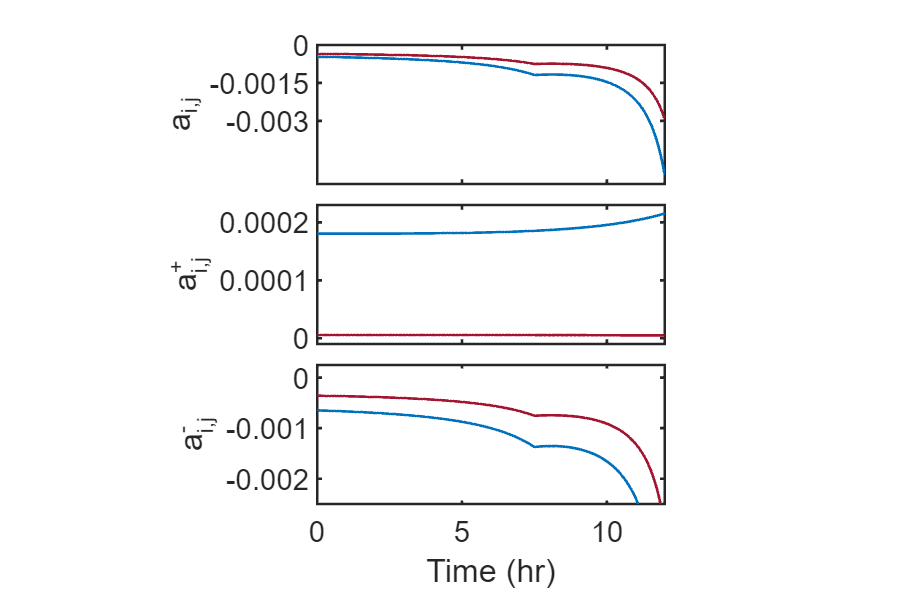

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
plot(T,a11,'linewidth',2,'Color','#0072BD')
hold on
plot(T,a22,'linewidth',2,'Color','#A2142F')
xlim([0 12])
ylim padded
yticks([-0.003 -0.0015 0])
yticklabels({'-0.003','-0.0015','0'})
ylabel('a_{i,j}')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,2),'linewidth',2,'Color','#0072BD') % cooperation
hold on
plot(T,a21(:,2),'linewidth',2,'Color','#A2142F') % cooperation
xlim([0 12])
ylim padded
yticks([0 0.0001 0.0002])
yticklabels({'0','0.0001','0.0002'})
ylabel('a_{i,j}^+')
set(gca,'linewidth',2,'fontsize',22)
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])
hold off

nexttile
plot(T,a12(:,1),'linewidth',2,'Color','#0072BD') % competition
hold on
plot(T,a21(:,1),'linewidth',2,'Color','#A2142F') % competition
xlim([0 12])
ylim([-0.0025 0.00025])
yticks([-0.002 -0.001 0])
yticklabels({'-0.002','-0.001','0'})
ylabel('a_{i,j}^-')
set(gca,'linewidth',2,'fontsize',22)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**We continue to run a few different experiments focusing on fed-batch experiments where different numbers of feed beads have been added as well as changing the time. Plotted are the concentrations of the substrates (top) and biomass (middle) over time, and the universal interaction factor, gamma (bottom).**

**Fig S3a (Left). Start with a concentration of 0.5 g/l glucose and 4 mg/l Trp & Tyr, and add 3FBs at 7.5 hrs**

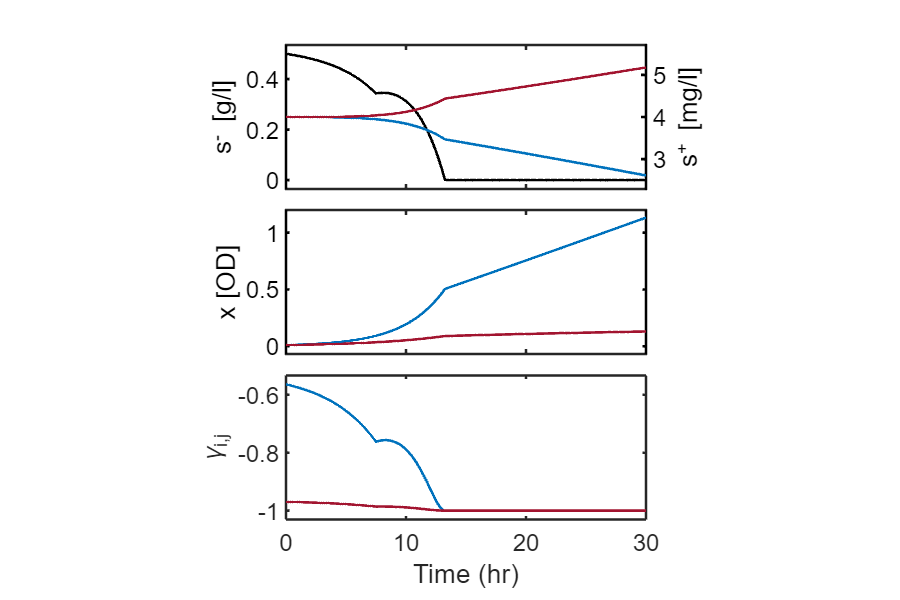

y0 =  [0.01 0.01 0.5 4 4];  %x1, x2, glc, trp, tyr
tAdd = 7.5;
tEnd = 30;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[~,~,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD') % coopetition
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'linewidth',2,'fontsize',18)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig S3a (Middle). Start with a concentration of 0.5 g/l glucose and 4 mg/l Trp & Tyr, and add 6FBs at 7.5 hrs**

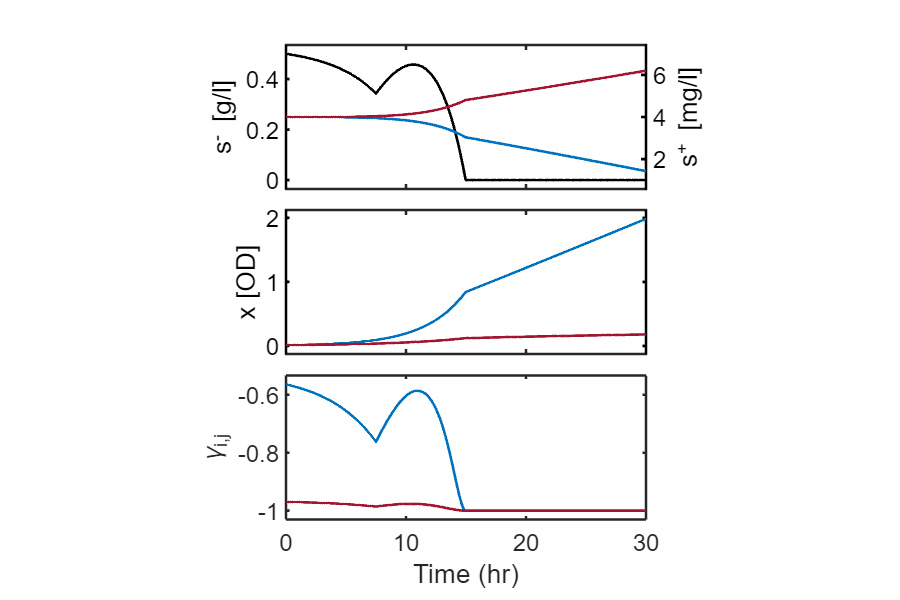

y0 =  [0.01 0.01 0.5 4 4];  %x1, x2, glc, trp, tyr
tAdd = 7.5;
tEnd = 30;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797*6/3;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[~,~,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD') % coopetition
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'linewidth',2,'fontsize',18)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig S3a (Right). Start with a concentration of 0.5 g/l glucose and 4 mg/l Trp & Tyr each, and add 10FBs at 7.5 hrs**

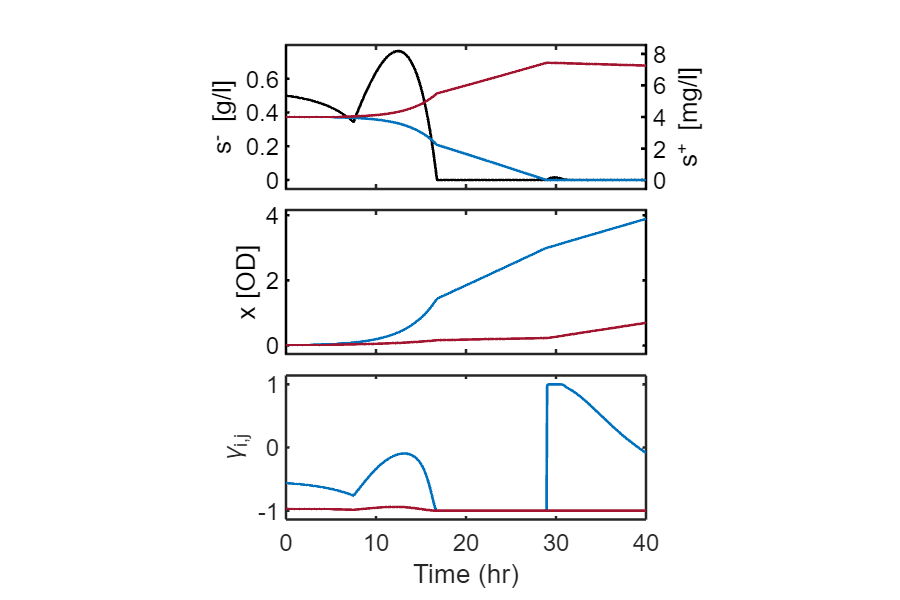

y0 =  [0.01 0.01 0.5 4 4];  %x1, x2, glc, trp, tyr
tAdd = 7.5;
tEnd = 40;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797*10/3;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[~,~,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded
xlim([0 40])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 40])
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD') % coopetition
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 40])
ylabel('\gamma_{i,j}')
set(gca,'linewidth',2,'fontsize',18)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig S3b (Left). Start with a concentration of 0.5 g/l glucose and 4 mg/l Trp & Tyr, and add 3FBs at 7.5 hrs**

y0 =  [0.01 0.01 0.5 4 4];  %x1, x2, glc, trp, tyr
tAdd = 7.5;
tEnd = 30;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[~,~,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD') % coopetition
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'linewidth',2,'fontsize',18)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig S3b (Middle). Start with a concentration of 0.5 g/l glucose and 4 mg/l Trp & Tyr, and add 6FBs at 7.5 hrs**

y0 =  [0.01 0.01 0.5 4 4];  %x1, x2, glc, trp, tyr
tAdd = 7.5;
tEnd = 30;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797*6/3;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[~,~,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD') % coopetition
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'linewidth',2,'fontsize',18)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig S3b (Right). Start with a concentration of 0.5 g/l glucose and 4 mg/l Trp & Tyr, and add 10FBs at 7.5 hrs**

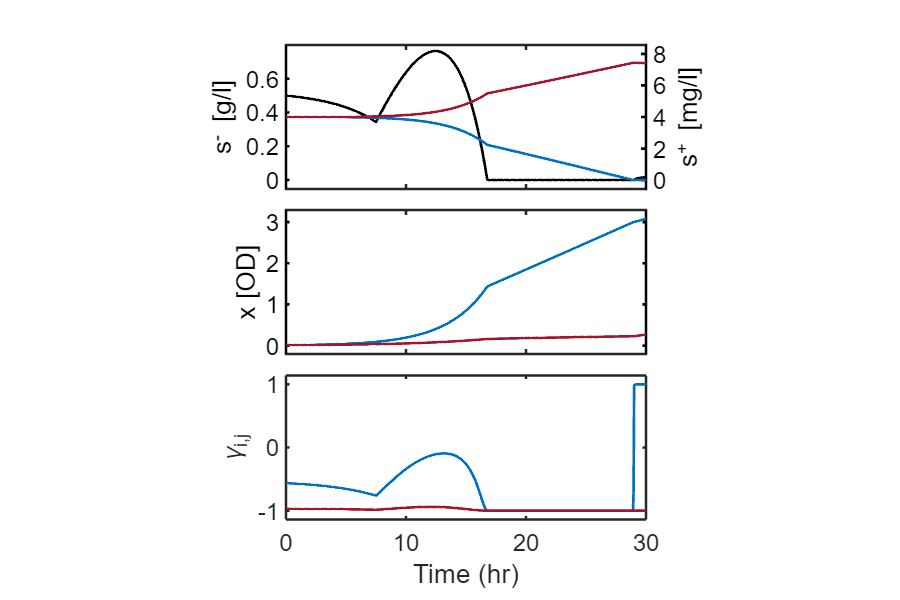

y0 =  [0.01 0.01 0.5 4 4];  %x1, x2, glc, trp, tyr
tAdd = 7.5;
tEnd = 30;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797*10/3;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[~,~,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD') % coopetition
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'linewidth',2,'fontsize',18)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig S3c (Left). Start with a concentration of 0.5 g/l glucose and 8 mg/l Trp & Tyr, and add 6FBs at 7.5 hrs**

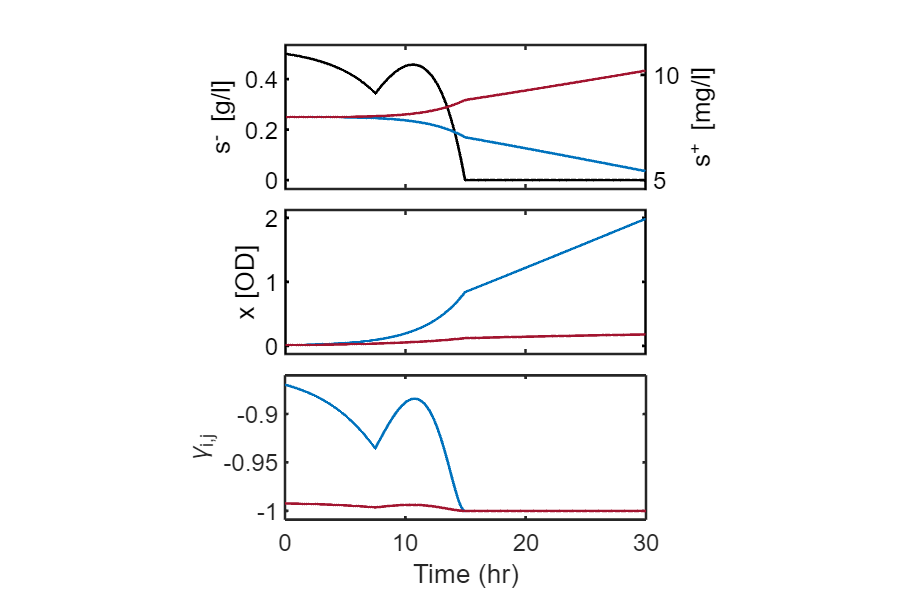

y0 =  [0.01 0.01 0.5 8 8];  %x1, x2, glc, trp, tyr
tAdd = 7.5;
tEnd = 30;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797*6/3;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[~,~,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD') % coopetition
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'linewidth',2,'fontsize',18)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig S3c (Middle). Start with a concentration of 0.5 g/l glucose and 8 mg/l Trp & Tyr, and add 6FBs at 10 hrs**

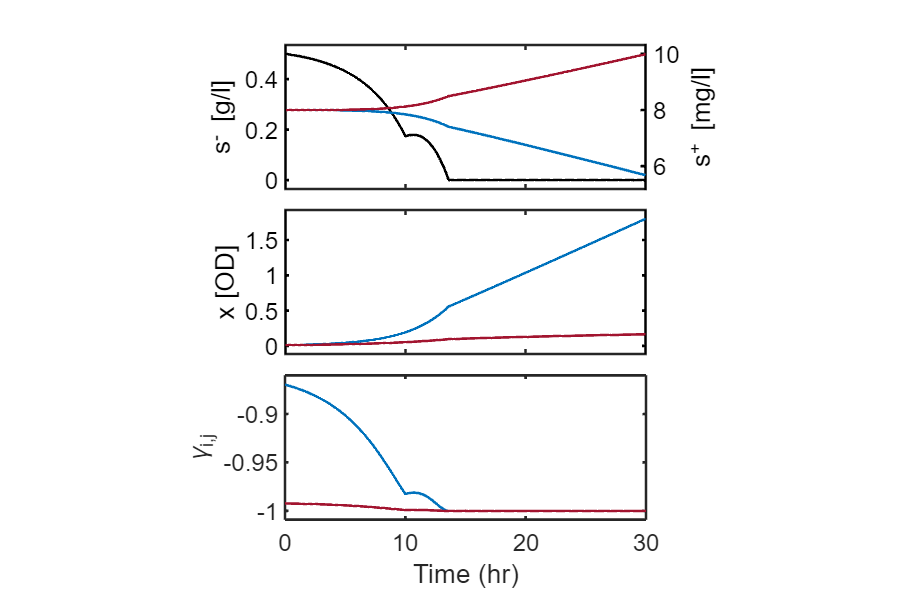

y0 =  [0.01 0.01 0.5 8 8];  %x1, x2, glc, trp, tyr
tAdd = 10;
tEnd = 30;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797*6/3;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[~,~,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD') % coopetition
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'linewidth',2,'fontsize',18)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**__________________________________________________________________________________**

**Fig S3c (Right). Start with a concentration of 0.5 g/l glucose and 8 mg/l Trp & Tyr, and add 6FBs at 15 hrs**

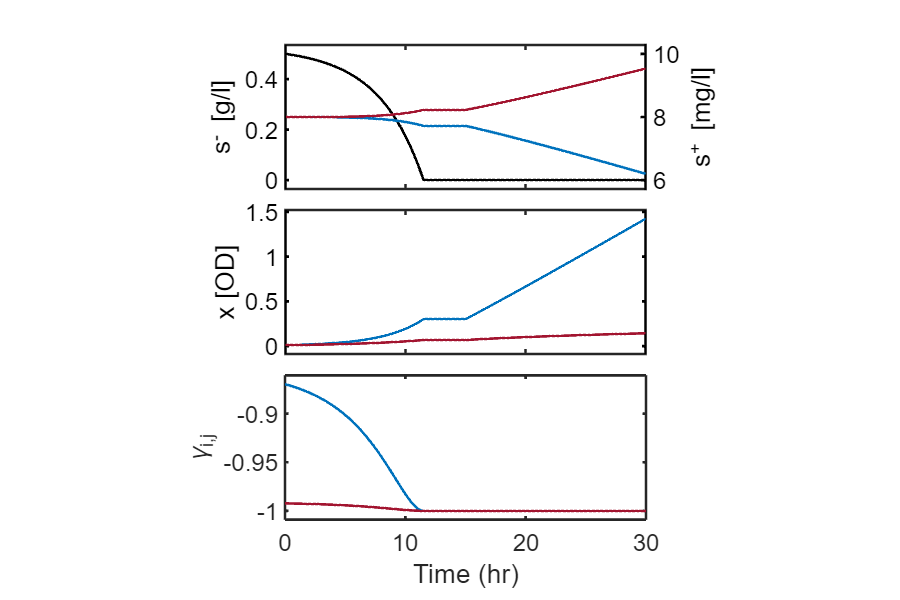

y0 =  [0.01 0.01 0.5 8 8];  %x1, x2, glc, trp, tyr
tAdd = 15;
tEnd = 30;
para = getPara;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tAdd/500:tAdd;

odeOptions=odeset('NonNegative',1:5);
[T1,Y1] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

y0=Y1(end,:);
tspan = tAdd:(tEnd-tAdd)/500:tEnd;
para.dGlc = 0.055797*6/3;
para.dTrp = 0;
para.dTyr = 0;
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

T=[T1(1:end-1);T2];
Y=[Y1(1:end-1,:);Y2];

[~,~,gam12,gam21,~,~,~,~,~,~,~]=getCoopetitionParameters(Y,para);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(3,1,'TileSpacing', "compact");

nexttile
yyaxis left
plot(T,Y(:,3),'k','linewidth',2,'LineStyle','-')
ylim padded
xlim([0 30])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
yyaxis right
plot(T,Y(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile
plot(T,Y(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T,Y(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 30])
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([2.5 1 1])

nexttile    
plot(T,gam12,'linewidth',2,'Color','#0072BD') % coopetition
hold on
plot(T,gam21,'linewidth',2,'Color','#A2142F')
ylim padded
xlim([0 30])
ylabel('\gamma_{i,j}')
set(gca,'linewidth',2,'fontsize',18)
xlabel('Time (hr)')
pbaspect([2.5 1 1])
hold off

**Fig S4. Lastly, we observe growth of the two isolates as a community with (solid line) and without (dashed line) cross-feeding. Glucose is not considered limited so we set Km to be 0 in the M-M kinetics. This way, rm is always equal to 1. Additionally, we start with 0.4 mg/l Trp & Tyr each.**

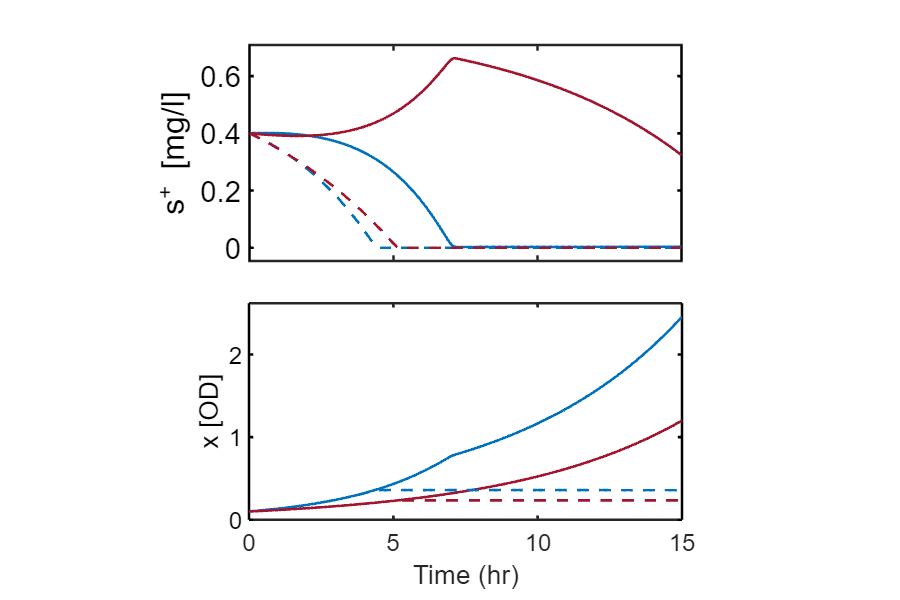

y0 =  [0.1 0.1 1000 0.4 0.4];  %x1, x2, glc, trp, tyr (the initial concentration of glucose does not affect the results because we set Km = 0)
tEnd = 15; %Time when experiment is done
para = getPara2;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;
tspan = 0:tEnd/500:tEnd;

odeOptions=odeset('RelTol',1e-5);
[T1,Y1] = ode23s(@odeKinetics,tspan,y0,odeOptions,para);

para = getPara3;
para.dGlc = 0;
para.dTrp = 0;
para.dTyr = 0;

odeOptions=odeset('NonNegative',1:5);
[T2,Y2] = ode15s(@odeKinetics,tspan,y0,odeOptions,para);

figure('Renderer', 'painters', 'Position', [10 10 900 600])
tiledlayout(2,1,'TileSpacing', "compact");

nexttile
xlim([0 tEnd])
ylabel('s^- [g/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
plot(T1,Y1(:,4),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T2,Y2(:,4),'Color','#0072BD','linewidth',2,'LineStyle','--')
plot(T1,Y1(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','-')
plot(T2,Y2(:,5),'Color','#A2142F','LineWidth',2,'LineStyle','--')
ylim padded 
ylabel('s^+ [mg/l]','color','k')
set(gca,'linewidth',2,'fontsize',22,'ycolor','k')
set(gca,'XTickLabel',[])
pbaspect([1 0.5 1])
hold off


nexttile
plot(T1,Y1(:,1),'Color','#0072BD','linewidth',2,'LineStyle','-')
hold on
plot(T1,Y1(:,2),'Color','#A2142F','linewidth',2,'LineStyle','-')
plot(T2,Y2(:,1),'Color','#0072BD','linewidth',2,'LineStyle','--')
plot(T2,Y2(:,2),'Color','#A2142F','linewidth',2,'LineStyle','--')
ylim padded
ylabel('x [OD]','color','k')
xlim([0 tEnd])
set(gca,'linewidth',2,'fontsize',18,'ycolor','k')
xlabel('Time (hr)')
pbaspect([1 0.5 1])
hold off

function para=getPara
% results from fitting datasets 1 to 12
x = [0.29613 0.1658 0.00030912 0.00039226 0.0033028 0.00038811 1.3715 1.7725 1.55 2.9608 1.3652 2.9943 0.00012064 4.0242e-07];

para.k=x(1:2);
para.Km=x(3:4);
para.Kp=x(5:6);
para.cm=x(7:8);
para.cp=[x(9:10);x(11:12)];
para.kd=[x(13),x(14)];
% para.dsm3fb=x(15);
% para.dsm5fb=x(16);
% para.dsm = 0;

%Texp
para.Texp_1=[
    0
    2
    4
    6
    8
    26.5
    71
    ];

para.Texp_2=para.Texp_1;
para.Texp_3=para.Texp_1;
para.Texp_4=para.Texp_1;
para.Texp_5=para.Texp_1;
para.Texp_6=para.Texp_1;

para.Texp_7=[
    0
    5
    7.5
    11.5
    15.3
    20
    24
    28
    32
    35.5
    50
    96.5
    ];

para.Texp_8=para.Texp_7;
para.Texp_9=para.Texp_7;

para.Texp_10=[
    0
    4
    6
    8
    10
    23
    25
    27
    29
    31
    33
    48
    72
    76
    80.5
    96
    101
    ];

para.Texp_11=para.Texp_10;
para.Texp_12=para.Texp_10;

%Yexp
para.Yexp_1=[...
    0.01	0	5.838
    0.073	0	5.817
    0.0555	0	5.836
    0.075	0	5.813
    0.077	0	5.630
    4.71	0	1.057
    3.75	0	0
];

para.Yexp_2=[...
    0.01	0	5.870
    0.049	0	5.903
    0.066	0	5.817
    0.0715	0	5.814
    0.0455	0	5.623
    4.625	0	0.863
    3.985	0	0
];

para.Yexp_3=[...
    0.01	0	5.936
    0.0585	0	5.840
    0.061	0	5.893
    0.068	0	5.870
    0.062	0	5.578
    5.19	0	0.354
    4.13	0	0
];

para.Yexp_4=[...
    0	0.01	5.920
    0	0.0575	5.828
    0	0.0625	5.859
    0	0.051	5.860
    0	0.0715	5.772
    0	2.3	3.596
    0	3.69	0
    ];

para.Yexp_5=[...
    0	0.01	5.909
    0	0.0615	5.828
    0	0.0815	5.804
    0	0.0875	5.800
    0	0.0765	5.514
    0	2.17	3.465
    0	3.68	0
    ];

para.Yexp_6=[...
    0	0.01	5.863
    0	0.04	5.782
    0	0.0595	5.783
    0	0.0835	5.807
    0	0.0695	5.805
    0	2.495	3.489
    0	3.775	0
];

para.Yexp_7=[...
    0.01	0.01	3.850866875
    0.045055779	0.059444221	3.77754375
    0.150295647	0.030704353	3.65848
    0.441860237	0.042139763	3.11358922
    0.532492507	0.062507493	2.535061563
    0.728283702	0.174216298	1.900054766
    1.030295204	0.369704796	1.129000332
    1.633220678	0.751779322	0
    1.447275905	0.617724095	0
    1.459967497	0.720032503	0
    1.525119291	0.694880709	0
    1.251902088	0.668097912	0
];

para.Yexp_8=[...
    0.01	0.01	0.625971641
    0.06368872	0.06031128	0.551883985
    0.156806058	0.031193942	0.465745459
    0.425509668	0.053490332	0.477764873
    0.63858444	0.08891556	0.140433172
    0.572302439	0.142697561	0
    0.590615092	0.429384908	0
    1.212595815	0.287404185	0
    1.225998801	0.319001199	0
    1.359891361	0.375108639	0
    1.663618358	0.391381642	0
    3.073401343	0.496598657	0
];

para.Yexp_9=[...
    0.01	0.01	0.620046719
    0.033472593	0.054027407	0.563267901
    0.133438409	0.025561591	0.455452275
    0.431651112	0.046348888	0.774531816
    0.60747779	0.08752221	0.561127178
    0.723527289	0.066472711	0.291307164
    0.828453	0.359047	0
    1.26669393	0.54330607	0
    1.403243245	0.646756755	0
    1.458349512	0.701650488	0
    1.853570475	0.821429525	0
    4.294153057	1.165846943	0
];

para.Yexp_10=[...
    0.02	2.879738438
    0.074	2.849546329
    0.106	2.544208008
    0.125	2.781907578
    0.1865	2.629840899
    1.252	1.759874375
    1.6325	1.518639258
    2.425	0.89132541
    3.19	0.150332979
    3.095	0
    2.94	0
    3.04	0
    2.69	0
    2.78	0
    2.59	0
    2.675	0
    2.965	0
];

para.Yexp_11=[...
    0.02	0.375339893
    0.094	0.363873086
    0.115	0.342330195
    0.1115	0.313701636
    0.216	0.224016636
    0.718	0
    0.9025	0
    1.1025	0
    1.2225	0
    1.415	0
    1.505	0
    2.125	0
    2.83	0
    3.095	0
    3.32	0
    3.72	0
    3.85	0
];

para.Yexp_12=[...
    0.02	0.377265459
    0.0865	0.344148618
    0.238	0.274335488
    0.6205	0.251656055
    1.694	0
    2.1375	0
    2.115	0
    2.48	0
    2.2	0
    2.68	0
    2.62	0
    3.795	0
    4.805	0
    4.83	0.024908468
    5.12	0
    6.67	0
    5.48	0
];

%std
para.Ystd_1=[...
    0	0	0.039328594
    0.001	0	0.009340781
    0.0045	0	0.02430625
    0.018	0	0.015077813
    0.006	0	0.080961562
    0.27	0	0.15644164
    0.24	0	0
    ];

para.Ystd_2=[...
    0	0	0.014097344
    0.006	0	0.005755156
    0.012	0	0.00862375
    0.0115	0	0.00644625
    0.0035	0	0.188979688
    0.085	0	0.265994688
    0.005	0	0
    ];

para.Ystd_3=[...
    0	0	0.030016094
    0.0005	0	0.02801875
    0.003	0	0.036962344
    0	0	0.03932625
    0.002	0	0.309389688
    0.05	0	0.129213731
    0.17	0	0
    ];

para.Ystd_4=[...
    0	0	0.009414219
    0	0.0085	0.015449688
    0	0.0005	0.001984532
    0	0.009	0.00867625
    0	0.0095	0.071830937
    0	0.34	0.579717969
    0	0.14	0
    ];

para.Ystd_5=[...
    0	0	0.01327
    0	0.0085	0.017167187
    0	0.0015	0.041077031
    0	0.0025	0.020152813
    0	0.0035	0.0395675
    0	0.59	0.689629375
    0	0.1	0
    ];

para.Ystd_6=[...
    0	0	0.026662812
    0	0.007	0.006621874
    0	0.0045	0.03061625
    0	0.0175	0.006392969
    0	0.0155	0.028409688
    0	2.045	2.077401328
    0	0.015	0
    ];

para.Ystd_7=[...
    0	0	0.013067997
    0.017533814	0.015412494	4.08793E-05
    0.022984335	0.006013772	0.003927978
    0.005879	0.002606281	0.027865532
    0.025508783	0.018437716	0.021837335
    0.046250293	0.112848732	0.026398065
    0.090777251	0.022359834	0.083928796
    0.10183037	0.26446493	0
    0.079273541	0.029776066	0
    0.034268813	0.119121627	0
    0.120514238	0.021519289	0
    0.30498704	0.106997142	0
    ];

para.Ystd_8=[...
    0	0	0.007070627
    0.004358486	0.012612077	0.000436694
    0.005326909	0.003912696	0.013083865
    0.025131973	0.006747197	0.017314242
    0.059504733	0.007670411	0.015119921
    0.061986774	0.008723904	0
    0.099855125	0.041566231	0
    0.047486585	0.047486585	0
    0.0759129	0.01227329	0
    0.085365855	0.021726244	0
    0.062546864	0.001092746	0
    0.438854928	0.027835547	0
    ];

para.Ystd_9=[...
    0	0	0.006736297
    0.01404518	0.002024365	0.016952678
    0.00243447	0.015950306	0.001290207
    0.035439545	0.001330007	0.026348318
    0.017126653	0.010055585	0.023066279
    0.045966404	0.03888641	0.065994946
    0.022191907	0.039869576	0
    0.289230225	0.048813919	0
    0.117779198	0.165063515	0
    0.109824303	0.158876274	0
    0.125874629	0.248891965	0
    0.747037195	0.412617926	0
    ];

para.Ystd_10=[...
    0	0.003273125
    0.006	0.031833672
    0.003	0.268334649
    0.007	0.083728047
    0.0175	0.191306758
    0.02	0.101562969
    0.1125	0.03283832
    0.125	0.033161348
    0	0.150332979
    0.175	0
    0.14	0
    0.17	0
    0.45	0
    0.14	0
    0.06	0
    0.175	0
    0.185	0
    ];

para.Ystd_11=[...
    0	0.005644111
    0.031	0.009972393
    0.005	0.004897207
    0.0015	0.000899253
    0.015	0.004896548
    0.042	0
    0.0075	0
    0.0575	0
    0.0325	0
    0.105	0
    0.07	0
    0.075	0
    0.05	0
    0.105	0
    0.34	0
    0.1	0
    0.07	0
    ];

para.Ystd_12=[...
    0	5.4541E-05
    0.0075	0.003589917
    0.01	0.000321592
    0.0235	0.043002656
    0.09	0
    0.1675	0
    0.205	0
    0.07	0
    0.2	0
    0.15	0
    0.36	0
    0.725	0
    0.965	0
    0.96	0.024908468
    1.14	0
    2.37	0
    1.06	0
    ];

end

function para=getPara2
% results from fitting datasets 1 to 12
x = [0.29613 0.1658 0 0 0.0033028 0.00038811 1.3715 1.7725 1.55 2.9608 1.3652 2.9943 0.00012064 4.0242e-07];

para.k=x(1:2);
para.Km=x(3:4);
para.Kp=x(5:6);
para.cm=x(7:8);
para.cp=[x(9:10);x(11:12)];
para.kd=[x(13),x(14)];

end

function para=getPara3
% results from fitting datasets 1 to 12
x = [0.29613 0.1658 0 0 0.0033028 0.00038811 1.3715 1.7725 1.55 0 0 2.9943 0.00012064 4.0242e-07];

para.k=x(1:2);
para.Km=x(3:4);
para.Kp=x(5:6);
para.cm=x(7:8);
para.cp=[x(9:10);x(11:12)];
para.kd=[x(13),x(14)];

end

function [dy,exFlux]=odeKinetics(~,y,para)

n = length(y);
dy = zeros(n,1); % a column vector
r = zeros(2,1);
rm = r;
rp = r;

k = para.k;
Km = para.Km;
Kp = para.Kp;
cm=para.cm;
cp=para.cp;
kd=para.kd;
dGlc = para.dGlc;
dTrp = para.dTrp;
dTyr = para.dTyr;
% dsm=para.dsm; %This is dependent on if FB or not. para.dsm for no FB, para.dsm3fb for 3FB and para.dsm5fb for 5FB.

x(1)=y(1);
x(2)=y(2);
sm=y(3);
sp=[y(4),y(5)]';

for i=1:2
    rm(i) = sm/(Km(i)+sm); % m = minus (i.e., inhibitive)
    rp(i) = sp(i)/(Kp(i)+sp(i)); % p = plus (i.e., promotive)
    r(i) = k(i)*rm(i)*rp(i);
end

for i = 1:2
    dy(i) = x(i)*r(i)-kd(i)*x(i);
end
dy(3) = -x(1)*r(1)*cm(1)  - x(2)*r(2)*cm(2) + dGlc;
dy(4) = -x(1)*r(1)*cp(1,1) + x(2)*r(2)*cp(1,2) + dTrp;
dy(5) =  x(1)*r(1)*cp(2,1) - x(2)*r(2)*cp(2,2) + dTyr;


% fed-batch
% dy(3)=dy(3)+dGlc;
% dy(4)=dy(4)+dTrp;
% dy(5)=dy(5)+dTyr;

% exchange fluxes
exFlux=[-r(1)*cm(1) -r(1)*cp(1,1) r(1)*cp(2,1) r(1) -r(2)*cm(2) r(2)*cp(1,2) -r(2)*cp(2,2) r(2) r(1)*x(1) r(2)*x(2)];
end

function [a12,a21,gam12,gam21,a11,a22,u10,u20,u1,u2,dyRel]=getCoopetitionParameters(Y,para)
n=size(Y,1);
a12=zeros(n,2);
a21=zeros(n,2);
gam12=zeros(n,1);
gam21=zeros(n,1);
a11=zeros(n,1);
a22=zeros(n,1);
u10=zeros(n,1);
u20=zeros(n,1);
u1=zeros(n,1);
u2=zeros(n,1);
dyRel=zeros(n,1);

r = zeros(2,1);
dudsm=zeros(2,1);
dudsp=zeros(2,1);
rm = r;
rp = r;

k = para.k;
Km = para.Km;
Kp = para.Kp;
cm=para.cm;
cp=para.cp;

for it=1:n
    y=Y(it,:);
    x(1)=y(1);
    x(2)=y(2);
    sm=y(3);
    sp=[y(4),y(5)]';

    for i=1:2
        rm(i) = sm/(Km(i)+sm);
        rp(i) = sp(i)/(Kp(i)+sp(i));
        r(i) = k(i)*rm(i)*rp(i);
        dudsm(i)=k(i)*rp(i)*Km(i)/(Km(i)+sm)^2;
        dudsp(i)=k(i)*rm(i)*Kp(i)/(Kp(i)+sp(i))^2;
    end

    a12(it,:)=[-dudsm(1)*cm(2) dudsp(1)*cp(1,2)];
    a21(it,:)=[-dudsm(2)*cm(1) dudsp(2)*cp(2,1)];
    a11(it,1)=-dudsm(1)*cm(1)-dudsp(1)*cp(1,1);
    a22(it,1)=-dudsm(2)*cm(2)-dudsp(2)*cp(2,2);
    u10(it,1)=r(1)-a11(it)*x(1)-sum(a12(it))*x(2);
    u20(it,1)=r(2)-a22(it)*x(2)-sum(a21(it))*x(1);
    u1(it,1)=r(1);
    u2(it,1)=r(2);
    
    
    gam12(it,1) = (a12(it,1)+a12(it,2))/(-a12(it,1)+a12(it,2));
    gam21(it,1) = (a21(it,1)+a21(it,2))/(-a21(it,1)+a21(it,2));
    
    yRel=x(1)/sum(x);
	dyRel(it) = yRel*(1-yRel)*(r(1)-r(2));
end 
end